clc,clear;
close all
syms theta1 theta2 theta3 r0 r1 r2 r3  ;



r1 = 4.5;
r2 = 3.2;
r3 = 4.5;
r0 = 8.8;
th2=[];
th3=[];
w = rad2deg(-0.5)

w = -28.6479

w1 = w;
assert (r1 + r2 + r3 > r0,"Not a valid Mechanism")
assert (r0 + r2 + r3 > r1,"Not a valid Mechanism")
assert (r1 + r0 + r3 > r2,"Not a valid Mechanism")
assert (r1 + r2 + r0 > r3,"Not a valid Mechanism")

%Limiting angles for theta 1
 rr0 = sqrt((r1+r3)^2+r2^2);
 
 theta1max = acos((- rr0^2 - r1^2 + (r3 + r2)^2)/(-2*r1*rr0)) - atan(r2/(r1+r3));
tmd = rad2deg(theta1max)

tmd = 33.0392

%tmdi = - ( acosd((r3^2 - (r1+r2)^2 - rr0^2) / ( -2*rr0*(r1+r2) )) + atand(r2/(r1+r3)));

tmdi = - ( acosd(((r2+r3)^2 - r1^2 - rr0^2) / ( -2*rr0*r1 )) + atand(r2/(r1+r3)));

time = -(tmd - tmdi)/w

time = 3.6730

t=0:0.01:time

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900





th1=( w*t + tmd)

th1 =    33.0392   32.7527   32.4662   32.1798   31.8933   31.6068   31.3203   31.0338   30.7474   30.4609   30.1744   29.8879   29.6014   29.3150   29.0285   28.7420   28.4555   28.1691   27.8826   27.5961   27.3096   27.0231   26.7367   26.4502   26.1637   25.8772   25.5907   25.3043   25.0178   24.7313   24.4448   24.1583   23.8719   23.5854   23.2989   23.0124   22.7260   22.4395   22.1530   21.8665   21.5800   21.2936   21.0071   20.7206   20.4341   20.1476   19.8612   19.5747   19.2882   19.0017





%Vector loop equations

F(1) = r1*cos(theta1) + r2*cos(theta2) == r0+ r3*cos(theta3)

$$F = \frac{9\,\cos\left(\theta_{1}\right)}{2}+\frac{16\,\cos\left(\theta_{2}\right)}{5}=\frac{9\,\cos\left(\theta_{3}\right)}{2}+\frac{44}{5}$$

F(2) = r1*sin(theta1) + r2*sin(theta2) == 0+ r3*sin(theta3);


%Create the initial point x0.  

x0 = [360 - (180 - (tmd/2));180 - (tmd/2)]

x0 =   196.5196
  163.4804



    
for i=1:length(th1)

    theta1 = th1(i)
    F = @(x) [+r1*cosd(theta1) + r2*cosd(x(1)) - r3*cosd(x(2)) - r0;
             +r1*sind(theta1) + r2*sind(x(1)) - r3*sind(x(2)) + r2];

     
    %Set options to return iterative display.

    options = optimoptions('fsolve','Display','iter');
    
    %Solve the equations.

    [x,fval] = fsolve(F,x0,options);
    th2 = [th2 x(1)] ;
    th3 = [th3 x(2)] ;
    x0 = [double(x(1));double(x(2))]
    disp( "pop")
end

theta1 = 33.0392


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         26.2978                         0.246               1
     1          6         25.7012              1          0.243               1
     2          9         24.2778            2.5          0.237             2.5
     3         12         21.0957           6.25          0.222            6.25
     4         15         14.6985         15.625          0.192            15.6
     5         18         2.92929        39.0625         0.0933            39.1
     6         21        0.231911        31.7111          0.033            97.7
     7         24      0.00467527        10.7451        0.00148            97.7
     8         27     3.19636e-05        3.25169       0.000111            97.7
     9         30     3.15233e-09       0.320692       9.57e-07            97.7



x0 =   298.9091
  140.6678


pop


theta1 = 32.7527


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000503736                      0.000538               1
     1          6     2.00606e-05              1       0.000114               1
     2          9     9.60782e-10       0.240941       6.29e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   297.9151
  141.4093


pop


theta1 = 32.4662


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000504858                      0.000569               1
     1          6     9.78601e-06              1       8.84e-05               1
     2          9     1.64637e-10       0.155555       2.84e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   296.9911
  142.1021


pop


theta1 = 32.1798


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000505673                      0.000598               1
     1          6     3.46088e-06              1       5.94e-05               1
     2          9     1.49166e-11      0.0857042       9.34e-08             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   296.1245
  142.7550


pop


theta1 = 31.8933


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506075                      0.000625               1
     1          6     4.44598e-07              1       2.73e-05               1
     2          9     1.40397e-13      0.0269438       1.04e-08             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   295.3061
  143.3747


pop


theta1 = 31.6068


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506232                      0.000651               1
     1          6     2.94343e-07       0.999744       1.19e-05               1
     2          9     8.61516e-14      0.0233743       6.76e-09             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   294.5292
  143.9660


pop


theta1 = 31.3203


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506236                      0.000676               1
     1          6      2.4202e-07       0.953055       1.12e-05               1
     2          9     4.88823e-14      0.0203158       5.31e-09            2.38

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   293.7883
  144.5328


pop


theta1 = 31.0338


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506239                      0.000701               1
     1          6     2.02293e-07        0.91228       1.06e-05               1
     2          9     2.90571e-14      0.0178649       4.26e-09            2.28

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   293.0794
  145.0781


pop


theta1 = 30.7474


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506241                      0.000724               1
     1          6     1.71431e-07       0.876258       1.01e-05               1
     2          9     1.79658e-14       0.015865       3.47e-09            2.19

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   292.3987
  145.6044


pop


theta1 = 30.4609


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506243                      0.000747               1
     1          6     1.46991e-07       0.844125       9.59e-06               1
     2          9     1.14887e-14      0.0142082       2.87e-09            2.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   291.7435
  146.1138


pop


theta1 = 30.1744


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506244                      0.000769               1
     1          6     1.27313e-07        0.81522       9.16e-06               1
     2          9     7.56265e-15      0.0128175        2.4e-09            2.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   291.1114
  146.6081


pop


theta1 = 29.8879


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506245                      0.000791               1
     1          6     1.11242e-07        0.78903       8.77e-06               1
     2          9     5.10688e-15      0.0116367       2.03e-09            1.97

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   290.5004
  147.0887


pop


theta1 = 29.6014


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506246                      0.000812               1
     1          6     9.79526e-08       0.765149       8.42e-06               1
     2          9     3.52624e-15      0.0106242       1.73e-09            1.91

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   289.9087
  147.5569


pop


theta1 = 29.3150


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506246                      0.000832               1
     1          6     8.68409e-08       0.743252       8.09e-06               1
     2          9      2.4836e-15     0.00974819        1.5e-09            1.86

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   289.3348
  148.0137


pop


theta1 = 29.0285


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000852               1
     1          6     7.74588e-08       0.723072       7.79e-06               1
     2          9     1.78089e-15     0.00898435        1.3e-09            1.81

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   288.7774
  148.4601


pop


theta1 = 28.7420


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000872               1
     1          6     6.94679e-08       0.704393       7.51e-06               1
     2          9     1.29744e-15     0.00831364       1.14e-09            1.76

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   288.2354
  148.8969


pop


theta1 = 28.4555


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000892               1
     1          6     6.26085e-08       0.687033       7.25e-06               1
     2          9     9.59017e-16     0.00772094       9.98e-10            1.72

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   287.7079
  149.3249


pop


theta1 = 28.1691


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                       0.00091               1
     1          6      5.6678e-08        0.67084          7e-06               1
     2          9     7.18237e-16     0.00719417       8.84e-10            1.68

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   287.1938
  149.7447


pop


theta1 = 27.8826


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000929               1
     1          6     5.15178e-08       0.655685       6.77e-06               1
     2          9     5.44296e-16     0.00672354       7.86e-10            1.64

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   286.6925
  150.1569


pop


theta1 = 27.5961


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000947               1
     1          6     4.70012e-08       0.641458       6.55e-06               1
     2          9     4.17068e-16     0.00630107       7.02e-10             1.6

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   286.2033
  150.5619


pop


theta1 = 27.3096


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000965               1
     1          6     4.30271e-08       0.628066       6.34e-06               1
     2          9     3.22901e-16     0.00592019        6.3e-10            1.57

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   285.7255
  150.9604


pop


theta1 = 27.0231


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000983               1
     1          6     3.95125e-08       0.615427       6.14e-06               1
     2          9     2.52295e-16     0.00557541       5.68e-10            1.54

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   285.2585
  151.3526


pop


theta1 = 26.7367


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                         0.001               1
     1          6     3.63908e-08        0.60347       5.95e-06               1
     2          9     1.98774e-16     0.00526217       5.14e-10            1.51

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   284.8018
  151.7390


pop


theta1 = 26.4502


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                       0.00102               1
     1          6     3.36058e-08       0.592134       5.77e-06               1
     2          9     1.57907e-16     0.00497659       4.67e-10            1.48

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   284.3550
  152.1200


pop


theta1 = 26.1637


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                       0.00103               1
     1          6      3.1112e-08       0.581364        5.6e-06               1
     2          9     1.26437e-16     0.00471542       4.26e-10            1.45

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   283.9176
  152.4958


pop


theta1 = 25.8772


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                       0.00105               1
     1          6     2.88708e-08       0.571114       5.43e-06               1
     2          9     1.01907e-16     0.00447587       3.89e-10            1.43

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   283.4892
  152.8668


pop


theta1 = 25.5907


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                       0.00107               1
     1          6     2.68497e-08        0.56134       5.27e-06               1
     2          9     8.26636e-17     0.00425554       3.57e-10             1.4

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   283.0696
  153.2332


pop


theta1 = 25.3043


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     2.50218e-08       0.552005       5.12e-06               1
     2          9     6.75037e-17     0.00405239       3.28e-10            1.38

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   282.6583
  153.5953


pop


theta1 = 25.0178


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6     2.33635e-08       0.543075       4.97e-06               1
     2          9     5.54523e-17     0.00386462       3.02e-10            1.36

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   282.2550
  153.9533


pop


theta1 = 24.7313


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6      2.1855e-08       0.534521       4.83e-06               1
     2          9     4.57733e-17     0.00369067       2.79e-10            1.34

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   281.8595
  154.3074


pop


theta1 = 24.4448


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     2.04795e-08       0.526315       4.69e-06               1
     2          9      3.8001e-17     0.00352923       2.59e-10            1.32

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   281.4716
  154.6579


pop


theta1 = 24.1583


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     1.92222e-08       0.518433       4.56e-06               1
     2          9     3.17021e-17     0.00337907        2.4e-10             1.3

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   281.0909
  155.0049


pop


theta1 = 23.8719


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     1.80703e-08       0.510854       4.43e-06               1
     2          9     2.65707e-17     0.00323916       2.24e-10            1.28

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   280.7173
  155.3486


pop


theta1 = 23.5854


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     1.70129e-08       0.503556       4.31e-06               1
     2          9     2.23706e-17     0.00310857       2.09e-10            1.26

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   280.3506
  155.6891


pop


theta1 = 23.2989


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     1.60404e-08       0.496523       4.19e-06               1
     2          9      1.8925e-17      0.0029865       1.95e-10            1.24

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   279.9905
  156.0267


pop


theta1 = 23.0124


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     1.51441e-08       0.489738       4.07e-06               1
     2          9     1.60673e-17     0.00287221       1.83e-10            1.22

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   279.6369
  156.3614


pop


theta1 = 22.7260


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6      1.4317e-08       0.483186       3.95e-06               1
     2          9     1.36985e-17     0.00276507       1.71e-10            1.21

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   279.2896
  156.6935


pop


theta1 = 22.4395


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     1.35521e-08       0.476853       3.84e-06               1
     2          9     1.17303e-17     0.00266448       1.61e-10            1.19

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   278.9485
  157.0229


pop


theta1 = 22.1530


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     1.28439e-08       0.470727       3.73e-06               1
     2          9      1.0077e-17     0.00256993       1.52e-10            1.18

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   278.6134
  157.3500


pop


theta1 = 21.8665


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     1.21873e-08       0.464795       3.63e-06               1
     2          9     8.68435e-18     0.00248096       1.43e-10            1.16

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   278.2842
  157.6746


pop


theta1 = 21.5800


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00127               1
     1          6     1.15776e-08       0.459049       3.53e-06               1
     2          9     7.51526e-18     0.00239714       1.35e-10            1.15

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   277.9608
  157.9971


pop


theta1 = 21.2936


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00128               1
     1          6     1.10108e-08       0.453477       3.45e-06               1
     2          9     6.52435e-18      0.0023181       1.28e-10            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   277.6430
  158.3174


pop


theta1 = 21.0071


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0013               1
     1          6     1.04832e-08       0.448071       3.43e-06               1
     2          9     5.68279e-18      0.0022435       1.21e-10            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   277.3308
  158.6357


pop


theta1 = 20.7206


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00131               1
     1          6     9.99179e-09       0.442823       3.41e-06               1
     2          9     4.96564e-18     0.00217303       1.15e-10            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   277.0240
  158.9521


pop


theta1 = 20.4341


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00132               1
     1          6     9.53343e-09       0.437725       3.39e-06               1
     2          9      4.3558e-18      0.0021064        1.1e-10            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   276.7225
  159.2667


pop


theta1 = 20.1476


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00133               1
     1          6     9.10549e-09        0.43277       3.37e-06               1
     2          9     3.83096e-18     0.00204335       1.04e-10            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   276.4263
  159.5794


pop


theta1 = 19.8612


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00135               1
     1          6     8.70574e-09       0.427951       3.35e-06               1
     2          9      3.3804e-18     0.00198367       9.95e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   276.1352
  159.8905


pop


theta1 = 19.5747


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00136               1
     1          6     8.33185e-09       0.423263       3.33e-06               1
     2          9     2.99096e-18     0.00192711        9.5e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.8491
  160.2000


pop


theta1 = 19.2882


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00137               1
     1          6     7.98207e-09       0.418699       3.31e-06               1
     2          9     2.65682e-18     0.00187352       9.09e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.5681
  160.5080


pop


theta1 = 19.0017


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00138               1
     1          6     7.65451e-09       0.414256       3.29e-06               1
     2          9      2.3623e-18     0.00182268        8.7e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.2920
  160.8145


pop


theta1 = 18.7152


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00139               1
     1          6     7.34762e-09       0.409927       3.28e-06               1
     2          9     2.11145e-18     0.00177446       8.34e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.0208
  161.1196


pop


theta1 = 18.4288


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0014               1
     1          6     7.05992e-09       0.405708       3.26e-06               1
     2          9     1.89241e-18     0.00172868       8.02e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  274.7543
  161.4234


pop


theta1 = 18.1423


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00141               1
     1          6     6.79011e-09       0.401596       3.25e-06               1
     2          9     1.70074e-18     0.00168522       7.71e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  274.4926
  161.7259


pop


theta1 = 17.8558


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00142               1
     1          6     6.53695e-09       0.397586       3.24e-06               1
     2          9     1.53376e-18     0.00164394       7.42e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  274.2356
  162.0272


pop


theta1 = 17.5693


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00144               1
     1          6     6.29931e-09       0.393674       3.22e-06               1
     2          9      1.3858e-18     0.00160473       7.16e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.9832
  162.3274


pop


theta1 = 17.2829


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00145               1
     1          6     6.07619e-09       0.389859       3.21e-06               1
     2          9     1.25687e-18     0.00156748       6.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.7353
  162.6265


pop


theta1 = 16.9964


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00146               1
     1          6     5.86668e-09       0.386135        3.2e-06               1
     2          9     1.14345e-18     0.00153209       6.68e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.4920
  162.9245


pop


theta1 = 16.7099


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00147               1
     1          6     5.66987e-09       0.382501       3.19e-06               1
     2          9     1.04262e-18     0.00149846       6.46e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.2532
  163.2215


pop


theta1 = 16.4234


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00148               1
     1          6     5.48498e-09       0.378953       3.18e-06               1
     2          9     9.54334e-19     0.00146651       6.26e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.0188
  163.5176


pop


theta1 = 16.1369


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00149               1
     1          6     5.31131e-09        0.37549       3.17e-06               1
     2          9     8.75569e-19     0.00143616       6.07e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.7888
  163.8128


pop


theta1 = 15.8505


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0015               1
     1          6     5.14812e-09       0.372108       3.16e-06               1
     2          9     8.06651e-19     0.00140732        5.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.5632
  164.1072


pop


theta1 = 15.5640


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00151               1
     1          6     4.99482e-09       0.368807       3.15e-06               1
     2          9     7.44249e-19     0.00137993       5.73e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.3419
  164.4007


pop


theta1 = 15.2775


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00151               1
     1          6     4.85085e-09       0.365583       3.14e-06               1
     2          9     6.89318e-19     0.00135393       5.58e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.1250
  164.6935


pop


theta1 = 14.9910


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00152               1
     1          6     4.71567e-09       0.362436       3.13e-06               1
     2          9     6.41002e-19     0.00132925       5.44e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.9122
  164.9855


pop


theta1 = 14.7045


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00153               1
     1          6     4.58872e-09       0.359362       3.13e-06               1
     2          9     5.97205e-19     0.00130584        5.3e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.7038
  165.2768


pop


theta1 = 14.4181


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00154               1
     1          6     4.46962e-09       0.356362       3.12e-06               1
     2          9      5.5779e-19     0.00128363       5.18e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.4995
  165.5675


pop


theta1 = 14.1316


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00155               1
     1          6     4.35785e-09       0.353432       3.11e-06               1
     2          9     5.23141e-19     0.00126259       5.06e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.2995
  165.8576


pop


theta1 = 13.8451


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00156               1
     1          6     4.25307e-09       0.350573       3.11e-06               1
     2          9     4.91731e-19     0.00124265       4.95e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.1036
  166.1471


pop


theta1 = 13.5586


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00157               1
     1          6     4.15489e-09       0.347782        3.1e-06               1
     2          9     4.63573e-19     0.00122378       4.85e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.9118
  166.4361


pop


theta1 = 13.2721


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00157               1
     1          6     4.06295e-09        0.34506        3.1e-06               1
     2          9     4.37958e-19     0.00120594       4.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.7242
  166.7245


pop


theta1 = 12.9857


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00158               1
     1          6     3.97692e-09       0.342403       3.09e-06               1
     2          9     4.15857e-19     0.00118908       4.67e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.5407
  167.0125


pop


theta1 = 12.6992


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00159               1
     1          6     3.89647e-09       0.339813       3.09e-06               1
     2          9     3.95132e-19     0.00117316       4.58e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.3612
  167.3000


pop


theta1 = 12.4127


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0016               1
     1          6     3.82137e-09       0.337288       3.09e-06               1
     2          9      3.7677e-19     0.00115815       4.51e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.1859
  167.5871


pop


theta1 = 12.1262


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00161               1
     1          6     3.75127e-09       0.334826       3.08e-06               1
     2          9     3.60262e-19     0.00114401       4.43e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.0146
  167.8738


pop


theta1 = 11.8398


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00161               1
     1          6     3.68595e-09       0.332428       3.08e-06               1
     2          9      3.4523e-19      0.0011307       4.37e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.8474
  168.1601


pop


theta1 = 11.5533


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00162               1
     1          6     3.62521e-09       0.330093       3.08e-06               1
     2          9     3.31951e-19     0.00111821       4.31e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.6842
  168.4461


pop


theta1 = 11.2668


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00163               1
     1          6     3.56872e-09       0.327821       3.07e-06               1
     2          9     3.20007e-19     0.00110649       4.25e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.5250
  168.7318


pop


theta1 = 10.9803


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00163               1
     1          6     3.51637e-09        0.32561       3.07e-06               1
     2          9     3.08971e-19     0.00109552       4.19e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.3698
  169.0172


pop


theta1 = 10.6938


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00164               1
     1          6     3.46787e-09       0.323461       3.07e-06               1
     2          9     2.99225e-19     0.00108526       4.15e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.2186
  169.3023


pop


theta1 = 10.4074


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00165               1
     1          6     3.42309e-09       0.321373       3.07e-06               1
     2          9     2.90343e-19     0.00107569        4.1e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.0715
  169.5872


pop


theta1 = 10.1209


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00165               1
     1          6     3.38178e-09       0.319345       3.07e-06               1
     2          9     2.82292e-19     0.00106678       4.06e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.9283
  169.8719


pop


theta1 = 9.8344


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00166               1
     1          6     3.34381e-09       0.317379       3.07e-06               1
     2          9     2.75138e-19     0.00105851       4.02e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.7891
  170.1564


pop


theta1 = 9.5479


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6       3.309e-09       0.315472       3.07e-06               1
     2          9     2.68887e-19     0.00105086       3.98e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.6539
  170.4407


pop


theta1 = 9.2614


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6     3.27721e-09       0.313626       3.07e-06               1
     2          9     2.62981e-19     0.00104379       3.95e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.5226
  170.7248


pop


theta1 = 8.9750


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     3.24829e-09        0.31184       3.07e-06               1
     2          9     2.57691e-19     0.00103729       3.92e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.3953
  171.0089


pop


theta1 = 8.6885


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     3.22206e-09       0.310114       3.07e-06               1
     2          9     2.53318e-19     0.00103132        3.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.2720
  171.2928


pop


theta1 = 8.4020


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     3.19842e-09       0.308448       3.07e-06               1
     2          9     2.49123e-19     0.00102588       3.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.1526
  171.5766


pop


theta1 = 8.1155


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     3.17718e-09       0.306842       3.07e-06               1
     2          9     2.45359e-19     0.00102093       3.85e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.0372
  171.8603


pop


theta1 = 7.8291


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6     3.15828e-09       0.305295       3.07e-06               1
     2          9     2.42168e-19     0.00101646       3.83e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.9258
  172.1440


pop


theta1 = 7.5426


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6     3.14157e-09       0.303809       3.07e-06               1
     2          9     2.39564e-19     0.00101244       3.82e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.8183
  172.4276


pop


theta1 = 7.2561


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     3.12687e-09       0.302382       3.07e-06               1
     2          9     2.36967e-19     0.00100885        3.8e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.7147
  172.7112


pop


theta1 = 6.9696


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     3.11419e-09       0.301016       3.07e-06               1
     2          9     2.34866e-19     0.00100569       3.79e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.6152
  172.9948


pop


theta1 = 6.6831


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     3.10334e-09       0.299709       3.07e-06               1
     2          9     2.33171e-19     0.00100291       3.78e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.5195
  173.2784


pop


theta1 = 6.3967


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     3.09422e-09       0.298463       3.07e-06               1
     2          9     2.31572e-19     0.00100051       3.77e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.4279
  173.5620


pop


theta1 = 6.1102


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     3.08671e-09       0.297277       3.08e-06               1
     2          9      2.3046e-19    0.000998465       3.76e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.3401
  173.8457


pop


theta1 = 5.8237


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.08079e-09       0.296151       3.08e-06               1
     2          9      2.2955e-19    0.000996764       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.2564
  174.1294


pop


theta1 = 5.5372


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.07628e-09       0.295085       3.08e-06               1
     2          9     2.28717e-19    0.000995378       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.1766
  174.4131


pop


theta1 = 5.2507


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.07314e-09        0.29408       3.08e-06               1
     2          9     2.28224e-19    0.000994299       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.1008
  174.6969


pop


theta1 = 4.9643


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.07124e-09       0.293135       3.08e-06               1
     2          9     2.28003e-19    0.000993503       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.0289
  174.9808


pop


theta1 = 4.6778


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.07052e-09       0.292251       3.09e-06               1
     2          9     2.27844e-19    0.000992976       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.9610
  175.2647


pop


theta1 = 4.3913


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.07086e-09       0.291428       3.09e-06               1
     2          9     2.27868e-19    0.000992697       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.8970
  175.5488


pop


theta1 = 4.1048


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.07222e-09       0.290665       3.09e-06               1
     2          9     2.28193e-19    0.000992654       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.8371
  175.8329


pop


theta1 = 3.8183


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.07452e-09       0.289962       3.09e-06               1
     2          9     2.28588e-19    0.000992835       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.7811
  176.1172


pop


theta1 = 3.5319


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.07763e-09       0.289321        3.1e-06               1
     2          9     2.28926e-19    0.000993213       3.76e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.7291
  176.4016


pop


theta1 = 3.2454


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.08151e-09        0.28874        3.1e-06               1
     2          9     2.29742e-19     0.00099378       3.76e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.6811
  176.6862


pop


theta1 = 2.9589


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6      3.0861e-09       0.288219        3.1e-06               1
     2          9     2.30524e-19    0.000994521       3.77e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.6371
  176.9708


pop


theta1 = 2.6724


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.09132e-09       0.287759       3.11e-06               1
     2          9     2.31389e-19    0.000995421       3.78e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.5970
  177.2556


pop


theta1 = 2.3860


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.09706e-09       0.287359       3.11e-06               1
     2          9     2.32294e-19    0.000996461       3.78e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.5610
  177.5406


pop


theta1 = 2.0995


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.10323e-09        0.28702       3.11e-06               1
     2          9     2.33409e-19    0.000997621       3.79e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.5290
  177.8257


pop


theta1 = 1.8130


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.10986e-09        0.28674       3.11e-06               1
     2          9     2.34492e-19    0.000998903        3.8e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.5010
  178.1110


pop


theta1 = 1.5265


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.11682e-09       0.286521       3.12e-06               1
     2          9     2.35733e-19     0.00100028       3.81e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4769
  178.3965


pop


theta1 = 1.2400


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.12409e-09        0.28636       3.12e-06               1
     2          9     2.36984e-19     0.00100175       3.82e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4569
  178.6821


pop


theta1 = 0.9536


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.13154e-09        0.28626       3.12e-06               1
     2          9     2.38354e-19     0.00100329       3.83e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4410
  178.9679


pop


theta1 = 0.6671


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.13912e-09       0.286218       3.13e-06               1
     2          9     2.39845e-19     0.00100489       3.84e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4290
  179.2538


pop


theta1 = 0.3806


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.14683e-09       0.286235       3.13e-06               1
     2          9     2.41081e-19     0.00100653       3.85e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4211
  179.5399


pop


theta1 = 0.0941


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.15456e-09       0.286309       3.13e-06               1
     2          9     2.42627e-19     0.00100821       3.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4172
  179.8262


pop


theta1 = -0.1924


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6      3.1623e-09       0.286442       3.13e-06               1
     2          9     2.44251e-19     0.00100992       3.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4173
  180.1127


pop


theta1 = -0.4788


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.16997e-09       0.286632       3.14e-06               1
     2          9     2.45699e-19     0.00101163       3.88e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4215
  180.3994


pop


theta1 = -0.7653


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6      3.1775e-09       0.286879       3.14e-06               1
     2          9     2.47152e-19     0.00101334       3.89e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4297
  180.6862


pop


theta1 = -1.0518


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.18483e-09       0.287181       3.14e-06               1
     2          9     2.48594e-19     0.00101504       3.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4419
  180.9732


pop


theta1 = -1.3383


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.19196e-09       0.287539       3.15e-06               1
     2          9     2.50047e-19     0.00101671       3.92e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4582
  181.2604


pop


theta1 = -1.6248


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.19879e-09       0.287952       3.15e-06               1
     2          9     2.51527e-19     0.00101834       3.93e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.4786
  181.5478


pop


theta1 = -1.9112


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.20532e-09       0.288419       3.15e-06               1
     2          9     2.53011e-19     0.00101993       3.94e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.5030
  181.8353


pop


theta1 = -2.1977


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.21149e-09       0.288939       3.15e-06               1
     2          9     2.54351e-19     0.00102146       3.94e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.5315
  182.1230


pop


theta1 = -2.4842


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.21722e-09       0.289512       3.15e-06               1
     2          9     2.55754e-19     0.00102291       3.95e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.5640
  182.4109


pop


theta1 = -2.7707


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.22255e-09       0.290136       3.16e-06               1
     2          9     2.56848e-19      0.0010243       3.96e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.6006
  182.6989


pop


theta1 = -3.0571


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.22738e-09       0.290811       3.16e-06               1
     2          9     2.58119e-19     0.00102559       3.97e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.6412
  182.9871


pop


theta1 = -3.3436


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.23168e-09       0.291536       3.16e-06               1
     2          9     2.59096e-19     0.00102678       3.97e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.6859
  183.2754


pop


theta1 = -3.6301


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.23544e-09       0.292309       3.16e-06               1
     2          9     2.60258e-19     0.00102787       3.98e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.7347
  183.5638


pop


theta1 = -3.9166


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.23864e-09        0.29313       3.16e-06               1
     2          9     2.61178e-19     0.00102884       3.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.7876
  183.8524


pop


theta1 = -4.2031


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.24122e-09       0.293998       3.16e-06               1
     2          9     2.61986e-19     0.00102968       3.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.8445
  184.1411


pop


theta1 = -4.4895


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.24314e-09       0.294912       3.17e-06               1
     2          9     2.62713e-19     0.00103039       3.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.9054
  184.4299


pop


theta1 = -4.7760


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.24441e-09       0.295869       3.17e-06               1
     2          9     2.63239e-19     0.00103096          4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  266.9705
  184.7189


pop


theta1 = -5.0625


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.24502e-09       0.296871       3.17e-06               1
     2          9     2.63684e-19     0.00103138          4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.0396
  185.0079


pop


theta1 = -5.3490


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.24491e-09       0.297914       3.17e-06               1
     2          9     2.64172e-19     0.00103164          4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.1127
  185.2970


pop


theta1 = -5.6355


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.24407e-09       0.298998       3.17e-06               1
     2          9     2.64286e-19     0.00103173          4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.1900
  185.5862


pop


theta1 = -5.9219


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.24255e-09       0.300121       3.17e-06               1
     2          9     2.64262e-19     0.00103166          4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.2712
  185.8755


pop


theta1 = -6.2084


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.24025e-09       0.301283       3.17e-06               1
     2          9     2.64114e-19     0.00103141       3.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.3566
  186.1648


pop


theta1 = -6.4949


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.23718e-09       0.302481       3.17e-06               1
     2          9     2.63617e-19     0.00103097       3.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.4459
  186.4542


pop


theta1 = -6.7814


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     3.23341e-09       0.303715       3.16e-06               1
     2          9     2.63394e-19     0.00103034       3.98e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.5394
  186.7435


pop


theta1 = -7.0679


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     3.22883e-09       0.304983       3.16e-06               1
     2          9     2.62613e-19     0.00102951       3.97e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.6368
  187.0329


pop


theta1 = -7.3543


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     3.22353e-09       0.306284       3.16e-06               1
     2          9     2.61744e-19     0.00102849       3.97e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.7383
  187.3223


pop


theta1 = -7.6408


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     3.21744e-09       0.307616       3.16e-06               1
     2          9     2.60681e-19     0.00102726       3.95e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.8439
  187.6117


pop


theta1 = -7.9273


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6     3.21064e-09       0.308978       3.16e-06               1
     2          9     2.59377e-19     0.00102582       3.94e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  267.9534
  187.9010


pop


theta1 = -8.2138


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6     3.20308e-09       0.310369       3.15e-06               1
     2          9      2.5795e-19     0.00102417       3.93e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.0670
  188.1903


pop


theta1 = -8.5002


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     3.19479e-09       0.311786       3.15e-06               1
     2          9      2.5626e-19      0.0010223       3.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.1846
  188.4796


pop


theta1 = -8.7867


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     3.18579e-09       0.313229       3.15e-06               1
     2          9     2.54271e-19     0.00102021        3.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.3061
  188.7687


pop


theta1 = -9.0732


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     3.17609e-09       0.314696       3.14e-06               1
     2          9     2.52232e-19      0.0010179       3.88e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.4317
  189.0577


pop


theta1 = -9.3597


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     3.16574e-09       0.316185       3.14e-06               1
     2          9     2.50032e-19     0.00101536       3.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.5612
  189.3467


pop


theta1 = -9.6462


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6     3.15472e-09       0.317696       3.13e-06               1
     2          9     2.47186e-19      0.0010126       3.83e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.6947
  189.6354


pop


theta1 = -9.9326


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6     3.14309e-09       0.319225       3.13e-06               1
     2          9     2.44495e-19     0.00100962       3.81e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.8322
  189.9241


pop


theta1 = -10.2191


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00166               1
     1          6     3.13081e-09       0.320773       3.12e-06               1
     2          9     2.41679e-19      0.0010064       3.79e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  268.9736
  190.2125


pop


theta1 = -10.5056


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00165               1
     1          6     3.11804e-09       0.322337       3.12e-06               1
     2          9     2.38233e-19     0.00100296       3.76e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.1190
  190.5007


pop


theta1 = -10.7921


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00165               1
     1          6     3.10469e-09       0.323916       3.11e-06               1
     2          9     2.34967e-19    0.000999295       3.73e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.2682
  190.7887


pop


theta1 = -11.0786


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00164               1
     1          6     3.09089e-09       0.325508       3.11e-06               1
     2          9     2.31255e-19    0.000995409        3.7e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.4214
  191.0764


pop


theta1 = -11.3650


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00163               1
     1          6     3.07657e-09       0.327112        3.1e-06               1
     2          9     2.27564e-19     0.00099129       3.67e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.5785
  191.3639


pop


theta1 = -11.6515


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00163               1
     1          6     3.06188e-09       0.328727       3.09e-06               1
     2          9     2.23392e-19    0.000986957       3.63e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.7394
  191.6511


pop


theta1 = -11.9380


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00162               1
     1          6     3.04681e-09        0.33035       3.08e-06               1
     2          9     2.19088e-19    0.000982406        3.6e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  269.9042
  191.9379


pop


theta1 = -12.2245


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00161               1
     1          6     3.03146e-09       0.331981       3.07e-06               1
     2          9     2.14783e-19    0.000977644       3.56e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.0729
  192.2244


pop


theta1 = -12.5110


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00161               1
     1          6     3.01581e-09       0.333617       3.06e-06               1
     2          9     2.10168e-19    0.000972672       3.52e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.2453
  192.5106


pop


theta1 = -12.7974


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0016               1
     1          6     2.99998e-09       0.335258       3.05e-06               1
     2          9     2.05328e-19    0.000967501       3.48e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.4216
  192.7963


pop


theta1 = -13.0839


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00159               1
     1          6     2.98396e-09       0.336902       3.04e-06               1
     2          9     2.00449e-19    0.000962127       3.44e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.6017
  193.0816


pop


theta1 = -13.3704


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00158               1
     1          6      2.9678e-09       0.338547       3.03e-06               1
     2          9     1.95328e-19    0.000956556       3.39e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.7855
  193.3665


pop


theta1 = -13.6569


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00158               1
     1          6     2.95163e-09       0.340192       3.02e-06               1
     2          9     1.90312e-19    0.000950808       3.35e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  270.9731
  193.6508


pop


theta1 = -13.9433


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00157               1
     1          6     2.93545e-09       0.341836       3.01e-06               1
     2          9     1.84766e-19    0.000944877        3.3e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.1644
  193.9347


pop


theta1 = -14.2298


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00156               1
     1          6     2.91937e-09       0.343477          3e-06               1
     2          9     1.79271e-19    0.000938784       3.25e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.3594
  194.2180


pop


theta1 = -14.5163


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00155               1
     1          6     2.90339e-09       0.345114       2.98e-06               1
     2          9     1.73614e-19    0.000932529        3.2e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.5580
  194.5007


pop


theta1 = -14.8028


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00154               1
     1          6     2.88758e-09       0.346745       2.97e-06               1
     2          9     1.68082e-19    0.000926117       3.15e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.7604
  194.7829


pop


theta1 = -15.0893


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00153               1
     1          6     2.87204e-09       0.348369       2.96e-06               1
     2          9     1.62145e-19    0.000919569       3.09e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  271.9663
  195.0644


pop


theta1 = -15.3757


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00153               1
     1          6     2.85685e-09       0.349985       2.94e-06               1
     2          9     1.56369e-19    0.000912898       3.04e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.1759
  195.3453


pop


theta1 = -15.6622


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00152               1
     1          6     2.84203e-09       0.351592       2.93e-06               1
     2          9     1.50551e-19    0.000906109       2.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.3891
  195.6254


pop


theta1 = -15.9487


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00151               1
     1          6     2.82768e-09       0.353188       2.91e-06               1
     2          9      1.4449e-19    0.000899219       2.93e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.6058
  195.9049


pop


theta1 = -16.2352


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0015               1
     1          6     2.81379e-09       0.354772       2.89e-06               1
     2          9     1.38696e-19     0.00089223       2.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  272.8260
  196.1836


pop


theta1 = -16.5217


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00149               1
     1          6      2.8005e-09       0.356343       2.88e-06               1
     2          9     1.32687e-19    0.000885168       2.81e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.0497
  196.4615


pop


theta1 = -16.8081


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00148               1
     1          6     2.78789e-09       0.357899       2.86e-06               1
     2          9     1.26883e-19    0.000878051       2.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.2769
  196.7386


pop


theta1 = -17.0946


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00147               1
     1          6     2.77593e-09        0.35944       2.84e-06               1
     2          9     1.20925e-19    0.000870878       2.69e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.5075
  197.0148


pop


theta1 = -17.3811


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00146               1
     1          6     2.76477e-09       0.360964       2.82e-06               1
     2          9     1.15292e-19    0.000863679       2.63e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.7416
  197.2901


pop


theta1 = -17.6676


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00145               1
     1          6     2.75443e-09       0.362471        2.8e-06               1
     2          9     1.09399e-19    0.000856463       2.57e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  273.9790
  197.5645


pop


theta1 = -17.9541


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00144               1
     1          6     2.74499e-09       0.363959       2.78e-06               1
     2          9     1.03978e-19    0.000849251       2.51e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  274.2198
  197.8380


pop


theta1 = -18.2405


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00143               1
     1          6     2.73649e-09       0.365427       2.76e-06               1
     2          9     9.82483e-20    0.000842058       2.44e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  274.4638
  198.1105


pop


theta1 = -18.5270


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00142               1
     1          6     2.72902e-09       0.366874       2.74e-06               1
     2          9     9.30074e-20    0.000834905       2.38e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  274.7112
  198.3819


pop


theta1 = -18.8135


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00141               1
     1          6     2.72259e-09       0.368299       2.72e-06               1
     2          9      8.7724e-20    0.000827804       2.31e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  274.9618
  198.6523


pop


theta1 = -19.1000


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0014               1
     1          6     2.71733e-09       0.369702        2.7e-06               1
     2          9     8.24758e-20    0.000820787       2.25e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.2156
  198.9215


pop


theta1 = -19.3864


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00139               1
     1          6      2.7132e-09       0.371081       2.68e-06               1
     2          9     7.77777e-20    0.000813854       2.19e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.4726
  199.1897


pop


theta1 = -19.6729


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00138               1
     1          6     2.71033e-09       0.372436       2.65e-06               1
     2          9     7.30386e-20    0.000807043       2.12e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.7328
  199.4567


pop


theta1 = -19.9594


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00137               1
     1          6     2.70874e-09       0.373766       2.63e-06               1
     2          9     6.86702e-20    0.000800365       2.06e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  275.9960
  199.7224


pop


theta1 = -20.2459


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00136               1
     1          6     2.70845e-09        0.37507       2.63e-06               1
     2          9     6.41418e-20    0.000793837       1.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.2624
  199.9870


pop


theta1 = -20.5324


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00135               1
     1          6     2.70954e-09       0.376347       2.69e-06               1
     2          9     6.02584e-20    0.000787483       1.93e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.5317
  200.2502


pop


theta1 = -20.8188


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00134               1
     1          6     2.71199e-09       0.377597       2.75e-06               1
     2          9     5.64972e-20    0.000781316       1.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8041
  200.5122


pop


theta1 = -21.1053


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00132               1
     1          6     2.71588e-09       0.378819       2.81e-06               1
     2          9     5.30277e-20    0.000775357        1.8e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.0794
  200.7727


pop


theta1 = -21.3918


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00131               1
     1          6     2.72128e-09       0.380012       2.87e-06               1
     2          9     4.98843e-20    0.000769636       1.74e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.3577
  201.0319


pop


theta1 = -21.6783


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0013               1
     1          6     2.72817e-09       0.381176       2.93e-06               1
     2          9     4.68992e-20    0.000764161       1.67e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.6388
  201.2897


pop


theta1 = -21.9648


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00129               1
     1          6     2.73655e-09        0.38231       2.99e-06               1
     2          9     4.42215e-20    0.000758944       1.61e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.9228
  201.5460


pop


theta1 = -22.2512


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00128               1
     1          6     2.74648e-09       0.383415       3.05e-06               1
     2          9     4.19722e-20    0.000754011       1.55e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.2096
  201.8008


pop


theta1 = -22.5377


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00127               1
     1          6     2.75804e-09       0.384489       3.11e-06               1
     2          9     3.99689e-20    0.000749385       1.49e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.4991
  202.0541


pop


theta1 = -22.8242


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     2.77109e-09       0.385531       3.17e-06               1
     2          9     3.83255e-20    0.000745059       1.43e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.7914
  202.3058


pop


theta1 = -23.1107


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     2.78582e-09       0.386543       3.23e-06               1
     2          9     3.70333e-20    0.000741073       1.37e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.0864
  202.5559


pop


theta1 = -23.3971


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     2.80208e-09       0.387523       3.29e-06               1
     2          9     3.61209e-20    0.000737416       1.31e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.3840
  202.8044


pop


theta1 = -23.6836


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     2.82003e-09       0.388471       3.35e-06               1
     2          9     3.53812e-20    0.000734124       1.25e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.6843
  203.0511


pop


theta1 = -23.9701


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6      2.8395e-09       0.389386       3.41e-06               1
     2          9     3.52807e-20    0.000731182        1.2e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.9871
  203.2962


pop


theta1 = -24.2566


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     2.86062e-09        0.39027       3.47e-06               1
     2          9     3.51607e-20    0.000728615       1.14e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.2924
  203.5395


pop


theta1 = -24.5431


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6      2.8833e-09       0.391121       3.52e-06               1
     2          9      3.5831e-20    0.000726422       1.09e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.6002
  203.7810


pop


theta1 = -24.8295


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     2.90758e-09       0.391939       3.58e-06               1
     2          9     3.65812e-20    0.000724616       1.03e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.9105
  204.0207


pop


theta1 = -25.1160


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     2.93343e-09       0.392725       3.64e-06               1
     2          9     3.77697e-20    0.000723194       9.84e-12               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.2232
  204.2585


pop


theta1 = -25.4025


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     2.96085e-09       0.393479        3.7e-06               1
     2          9     3.93214e-20    0.000722165       1.01e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.5382
  204.4944


pop


theta1 = -25.6890


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     2.98976e-09       0.394199       3.75e-06               1
     2          9     4.09219e-20    0.000721519       1.06e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.8555
  204.7284


pop


theta1 = -25.9755


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     3.02016e-09       0.394887       3.81e-06               1
     2          9     4.32329e-20    0.000721256        1.1e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.1752
  204.9604


pop


theta1 = -26.2619


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     3.05207e-09       0.395543       3.86e-06               1
     2          9     4.55604e-20    0.000721383       1.15e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.4970
  205.1904


pop


theta1 = -26.5484


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6      3.0854e-09       0.396166       3.92e-06               1
     2          9      4.8606e-20    0.000721886        1.2e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.8211
  205.4183


pop


theta1 = -26.8349


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6     3.12011e-09       0.396758       3.97e-06               1
     2          9     5.15381e-20    0.000722755       1.25e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.1473
  205.6442


pop


theta1 = -27.1214


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     3.15618e-09       0.397317       4.02e-06               1
     2          9     5.51162e-20    0.000723989        1.3e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.4756
  205.8680


pop


theta1 = -27.4079


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00106               1
     1          6     3.19359e-09       0.397845       4.08e-06               1
     2          9     5.89703e-20    0.000725578       1.35e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.8060
  206.0897


pop


theta1 = -27.6943


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00105               1
     1          6     3.23224e-09       0.398341       4.13e-06               1
     2          9     6.30575e-20    0.000727504        1.4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.1384
  206.3091


pop


theta1 = -27.9808


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00104               1
     1          6     3.27212e-09       0.398807       4.18e-06               1
     2          9      6.7491e-20    0.000729761       1.45e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.4729
  206.5264


pop


theta1 = -28.2673


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00102               1
     1          6     3.31319e-09       0.399242       4.23e-06               1
     2          9     7.23491e-20    0.000732334        1.5e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.8092
  206.7414


pop


theta1 = -28.5538


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6     3.35536e-09       0.399647       4.28e-06               1
     2          9     7.72397e-20    0.000735208       1.55e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.1475
  206.9541


pop


theta1 = -28.8402


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000997               1
     1          6     3.39859e-09       0.400022       4.33e-06               1
     2          9     8.24868e-20    0.000738366        1.6e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.4876
  207.1645


pop


theta1 = -29.1267


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000984               1
     1          6     3.44285e-09       0.400367       4.38e-06               1
     2          9     8.78817e-20    0.000741796       1.66e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.8296
  207.3726


pop


theta1 = -29.4132


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000972               1
     1          6     3.48801e-09       0.400684       4.43e-06               1
     2          9     9.33018e-20    0.000745475        1.7e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.1734
  207.5783


pop


theta1 = -29.6997


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000959               1
     1          6     3.53409e-09       0.400973       4.48e-06               1
     2          9     9.94002e-20    0.000749393       1.76e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.5189
  207.7817


pop


theta1 = -29.9862


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000946               1
     1          6       3.581e-09       0.401234       4.52e-06               1
     2          9     1.05312e-19    0.000753531       1.81e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.8661
  207.9826


pop


theta1 = -30.2726


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000934               1
     1          6     3.62866e-09       0.401468       4.57e-06               1
     2          9     1.11624e-19    0.000757867       1.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.2150
  208.1810


pop


theta1 = -30.5591


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000928               1
     1          6     3.67702e-09       0.401676       4.61e-06               1
     2          9     1.17902e-19    0.000762387       1.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.5655
  208.3769


pop


theta1 = -30.8456


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000938               1
     1          6     3.72598e-09       0.401858       4.66e-06               1
     2          9     1.24462e-19    0.000767069       1.96e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.9176
  208.5703


pop


theta1 = -31.1321


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000947               1
     1          6     3.77553e-09       0.402015        4.7e-06               1
     2          9     1.31085e-19    0.000771902       2.01e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.2713
  208.7612


pop


theta1 = -31.4186


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000956               1
     1          6     3.82559e-09       0.402147       4.75e-06               1
     2          9     1.37957e-19    0.000776866       2.06e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.6265
  208.9495


pop


theta1 = -31.7050


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000965               1
     1          6     3.87605e-09       0.402256       4.79e-06               1
     2          9     1.45058e-19    0.000781939       2.11e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.9832
  209.1352


pop


theta1 = -31.9915


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000974               1
     1          6     3.92687e-09       0.402343       4.83e-06               1
     2          9      1.5185e-19    0.000787109       2.16e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.3413
  209.3183


pop


theta1 = -32.2780


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000983               1
     1          6     3.97804e-09       0.402407       4.87e-06               1
     2          9     1.59098e-19    0.000792363       2.21e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.7008
  209.4987


pop


theta1 = -32.5645


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000992               1
     1          6     4.02941e-09        0.40245       4.91e-06               1
     2          9     1.66452e-19    0.000797679       2.26e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.0617
  209.6764


pop


theta1 = -32.8510


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                         0.001               1
     1          6     4.08096e-09       0.402473       4.95e-06               1
     2          9     1.73591e-19    0.000803044       2.31e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.4239
  209.8514


pop


theta1 = -33.1374


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6     4.13259e-09       0.402477       4.99e-06               1
     2          9     1.80661e-19    0.000808442       2.36e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.7875
  210.0237


pop


theta1 = -33.4239


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00102               1
     1          6     4.18429e-09       0.402462       5.03e-06               1
     2          9     1.88024e-19    0.000813864        2.4e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.1523
  210.1932


pop


theta1 = -33.7104


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00103               1
     1          6     4.23598e-09       0.402429       5.06e-06               1
     2          9     1.95133e-19    0.000819293       2.45e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.5184
  210.3600


pop


theta1 = -33.9969


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00103               1
     1          6     4.28756e-09        0.40238        5.1e-06               1
     2          9     2.02645e-19    0.000824714       2.49e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.8856
  210.5239


pop


theta1 = -34.2833


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00104               1
     1          6     4.33903e-09       0.402315       5.14e-06               1
     2          9     2.09797e-19     0.00083012       2.54e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.2540
  210.6850


pop


theta1 = -34.5698


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00105               1
     1          6     4.39024e-09       0.402235       5.17e-06               1
     2          9     2.17204e-19    0.000835492       2.58e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.6236
  210.8433


pop


theta1 = -34.8563


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00106               1
     1          6     4.44127e-09       0.402141        5.2e-06               1
     2          9     2.24774e-19    0.000840832       2.63e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.9943
  210.9987


pop


theta1 = -35.1428


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     4.49199e-09       0.402034       5.24e-06               1
     2          9     2.31863e-19    0.000846122       2.67e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  293.3661
  211.1511


pop


theta1 = -35.4293


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     4.54232e-09       0.401916       5.27e-06               1
     2          9      2.3915e-19    0.000851351       2.71e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  293.7389
  211.3007


pop


theta1 = -35.7157


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     4.59227e-09       0.401787        5.3e-06               1
     2          9     2.46077e-19    0.000856516       2.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  294.1127
  211.4474


pop


theta1 = -36.0022


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6     4.64176e-09       0.401648       5.33e-06               1
     2          9     2.53084e-19    0.000861609       2.79e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  294.4876
  211.5911


pop


theta1 = -36.2887


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6     4.69075e-09       0.401501       5.36e-06               1
     2          9     2.60158e-19     0.00086662       2.83e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  294.8634
  211.7318


pop


theta1 = -36.5752


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6     4.73919e-09       0.401346       5.39e-06               1
     2          9     2.66997e-19    0.000871544       2.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  295.2401
  211.8695


pop


theta1 = -36.8617


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     4.78709e-09       0.401184       5.42e-06               1
     2          9     2.74119e-19    0.000876381       2.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  295.6178
  212.0042


pop


theta1 = -37.1481


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     4.83438e-09       0.401017       5.45e-06               1
     2          9     2.80373e-19    0.000881122       2.94e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  295.9963
  212.1359


pop


theta1 = -37.4346


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     4.88099e-09       0.400846       5.48e-06               1
     2          9     2.87107e-19     0.00088576       2.98e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  296.3758
  212.2645


pop


theta1 = -37.7211


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     4.92697e-09       0.400671       5.51e-06               1
     2          9     2.93401e-19    0.000890299       3.01e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  296.7560
  212.3901


pop


theta1 = -38.0076


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     4.97222e-09       0.400494       5.53e-06               1
     2          9     2.99983e-19    0.000894733       3.05e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  297.1371
  212.5126


pop


theta1 = -38.2941


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     5.01677e-09       0.400316       5.56e-06               1
     2          9     3.06525e-19    0.000899061       3.08e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  297.5190
  212.6320


pop


theta1 = -38.5805


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     5.06057e-09       0.400138       5.58e-06               1
     2          9     3.12269e-19    0.000903282       3.11e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  297.9016
  212.7483


pop


theta1 = -38.8670


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     5.10365e-09       0.399961       5.61e-06               1
     2          9     3.18771e-19    0.000907399       3.14e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  298.2850
  212.8614


pop


theta1 = -39.1535


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     5.14595e-09       0.399786       5.63e-06               1
     2          9     3.24137e-19    0.000911409       3.17e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  298.6692
  212.9714


pop


theta1 = -39.4400


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     5.18744e-09       0.399615       5.65e-06               1
     2          9     3.30112e-19    0.000915312        3.2e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  299.0540
  213.0783


pop


theta1 = -39.7264


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     5.22817e-09       0.399448       5.68e-06               1
     2          9     3.36331e-19    0.000919113       3.23e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  299.4396
  213.1820


pop


theta1 = -40.0129


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     5.26809e-09       0.399287        5.7e-06               1
     2          9     3.41683e-19    0.000922811       3.26e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  299.8258
  213.2825


pop


theta1 = -40.2994


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     5.30727e-09       0.399132       5.72e-06               1
     2          9     3.47153e-19    0.000926417       3.29e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  300.2127
  213.3798


pop


theta1 = -40.5859


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     5.34562e-09       0.398985       5.74e-06               1
     2          9     3.52605e-19    0.000929925       3.31e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  300.6002
  213.4740


pop


theta1 = -40.8724


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     5.38323e-09       0.398848       5.76e-06               1
     2          9     3.57616e-19    0.000933346       3.34e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  300.9884
  213.5648


pop


theta1 = -41.1588


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     5.42009e-09        0.39872       5.78e-06               1
     2          9     3.62887e-19    0.000936684       3.36e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  301.3772
  213.6525


pop


theta1 = -41.4453


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6      5.4562e-09       0.398604        5.8e-06               1
     2          9     3.68162e-19    0.000939944       3.39e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  301.7666
  213.7369


pop


theta1 = -41.7318


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     5.49158e-09         0.3985       5.82e-06               1
     2          9      3.7279e-19    0.000943132       3.41e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  302.1566
  213.8181


pop


theta1 = -42.0183


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     5.52627e-09        0.39841       5.84e-06               1
     2          9     3.77809e-19    0.000946256       3.43e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  302.5471
  213.8960


pop


theta1 = -42.3048


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     5.56027e-09       0.398335       5.85e-06               1
     2          9     3.83307e-19    0.000949323       3.46e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  302.9383
  213.9706


pop


theta1 = -42.5912


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     5.59363e-09       0.398275       5.87e-06               1
     2          9     3.87256e-19    0.000952342       3.48e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  303.3300
  214.0420


pop


theta1 = -42.8777


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6      5.6264e-09       0.398232       5.89e-06               1
     2          9     3.92347e-19    0.000955323        3.5e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  303.7222
  214.1100


pop


theta1 = -43.1642


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     5.65863e-09       0.398207        5.9e-06               1
     2          9     3.96723e-19    0.000958277       3.52e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  304.1150
  214.1747


pop


theta1 = -43.4507


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6      5.6903e-09       0.398201       5.92e-06               1
     2          9     4.01792e-19     0.00096121       3.54e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  304.5084
  214.2362


pop


theta1 = -43.7372


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     5.72149e-09       0.398216       5.94e-06               1
     2          9     4.06722e-19    0.000964134       3.56e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  304.9022
  214.2943


pop


theta1 = -44.0236


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     5.75227e-09       0.398252       5.95e-06               1
     2          9     4.10812e-19    0.000967064       3.58e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  305.2966
  214.3490


pop


theta1 = -44.3101


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     5.78265e-09        0.39831       5.97e-06               1
     2          9       4.154e-19    0.000970009        3.6e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  305.6915
  214.4005


pop


theta1 = -44.5966


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     5.81274e-09       0.398392       5.98e-06               1
     2          9     4.20393e-19    0.000972984       3.62e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  306.0869
  214.4485


pop


theta1 = -44.8831


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     5.84257e-09       0.398499          6e-06               1
     2          9     4.24713e-19    0.000976002       3.64e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  306.4829
  214.4932


pop


theta1 = -45.1695


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     5.87222e-09       0.398632       6.01e-06               1
     2          9     4.29883e-19    0.000979078       3.66e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  306.8793
  214.5346


pop


theta1 = -45.4560


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     5.90174e-09       0.398792       6.02e-06               1
     2          9     4.34788e-19    0.000982225       3.68e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  307.2763
  214.5726


pop


theta1 = -45.7425


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     5.93123e-09       0.398979       6.04e-06               1
     2          9     4.40078e-19    0.000985462        3.7e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  307.6738
  214.6072


pop


theta1 = -46.0290


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     5.96077e-09       0.399196       6.05e-06               1
     2          9     4.44724e-19    0.000988805       3.72e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  308.0717
  214.6383


pop


theta1 = -46.3155


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     5.99042e-09       0.399444       6.06e-06               1
     2          9     4.50126e-19     0.00099227       3.74e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  308.4702
  214.6661


pop


theta1 = -46.6019


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.02028e-09       0.399722       6.08e-06               1
     2          9      4.5559e-19    0.000995876       3.76e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  308.8693
  214.6905


pop


theta1 = -46.8884


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.05045e-09       0.400034       6.09e-06               1
     2          9     4.61352e-19    0.000999641       3.78e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  309.2688
  214.7115


pop


theta1 = -47.1749


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6       6.081e-09       0.400379        6.1e-06               1
     2          9     4.66987e-19     0.00100358        3.8e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  309.6689
  214.7291


pop


theta1 = -47.4614


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.11207e-09       0.400759       6.12e-06               1
     2          9     4.73339e-19     0.00100773       3.82e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  310.0695
  214.7432


pop


theta1 = -47.7479


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.14375e-09       0.401174       6.13e-06               1
     2          9      4.7919e-19     0.00101209       3.84e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  310.4706
  214.7538


pop


theta1 = -48.0343


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.17616e-09       0.401627       6.14e-06               1
     2          9     4.86405e-19      0.0010167       3.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  310.8723
  214.7611


pop


theta1 = -48.3208


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.20941e-09       0.402118       6.15e-06               1
     2          9     4.93284e-19     0.00102158       3.89e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  311.2745
  214.7648


pop


theta1 = -48.6073


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.24361e-09       0.402649       6.16e-06               1
     2          9     5.00538e-19     0.00102675       3.91e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  311.6774
  214.7651


pop


theta1 = -48.8938


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.27893e-09        0.40322       6.18e-06               1
     2          9     5.09055e-19     0.00103223       3.94e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  312.0807
  214.7620


pop


theta1 = -49.1803


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.31545e-09       0.403833       6.19e-06               1
     2          9     5.17628e-19     0.00103805       3.97e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  312.4847
  214.7553


pop


theta1 = -49.4667


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.35336e-09       0.404488        6.2e-06               1
     2          9     5.25954e-19     0.00104424       3.99e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  312.8893
  214.7452


pop


theta1 = -49.7532


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.39282e-09       0.405188       6.21e-06               1
     2          9     5.35776e-19     0.00105083       4.02e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  313.2945
  214.7315


pop


theta1 = -50.0397


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.43395e-09       0.405933       6.22e-06               1
     2          9     5.45981e-19     0.00105784       4.05e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  313.7003
  214.7143


pop


theta1 = -50.3262


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.47695e-09       0.406725       6.24e-06               1
     2          9     5.57596e-19     0.00106531       4.09e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  314.1068
  214.6937


pop


theta1 = -50.6126


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.52192e-09       0.407564       6.25e-06               1
     2          9     5.68919e-19     0.00107326       4.12e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  314.5140
  214.6695


pop


theta1 = -50.8991


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.56914e-09       0.408453       6.26e-06               1
     2          9     5.81756e-19     0.00108173       4.15e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  314.9218
  214.6417


pop


theta1 = -51.1856


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.61875e-09       0.409391       6.27e-06               1
     2          9      5.9606e-19     0.00109076       4.19e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  315.3304
  214.6104


pop


theta1 = -51.4721


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.67094e-09       0.410382       6.29e-06               1
     2          9     6.11272e-19     0.00110036       4.23e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  315.7397
  214.5755


pop


theta1 = -51.7586


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.72595e-09       0.411426        6.3e-06               1
     2          9     6.27741e-19     0.00111059       4.28e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  316.1497
  214.5371


pop


theta1 = -52.0450


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.78399e-09       0.412524       6.31e-06               1
     2          9     6.45409e-19     0.00112147       4.32e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  316.5605
  214.4950


pop


theta1 = -52.3315


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.84529e-09       0.413678       6.33e-06               1
     2          9     6.63711e-19     0.00113305       4.36e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  316.9721
  214.4494


pop


theta1 = -52.6180


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.91014e-09       0.414889       6.34e-06               1
     2          9     6.84553e-19     0.00114537       4.41e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  317.3846
  214.4001


pop


theta1 = -52.9045


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.97873e-09       0.416159       6.35e-06               1
     2          9     7.07525e-19     0.00115846       4.46e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  317.7979
  214.3473


pop


theta1 = -53.1910


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     7.05139e-09        0.41749       6.37e-06               1
     2          9      7.3303e-19     0.00117237       4.52e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  318.2121
  214.2907


pop


theta1 = -53.4774


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6      7.1284e-09       0.418882       6.38e-06               1
     2          9     7.60191e-19     0.00118715       4.58e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  318.6272
  214.2306


pop


theta1 = -53.7639


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6      7.2101e-09       0.420338        6.4e-06               1
     2          9     7.89547e-19     0.00120284       4.64e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  319.0433
  214.1667


pop


theta1 = -54.0504


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     7.29677e-09        0.42186       6.41e-06               1
     2          9     8.23252e-19     0.00121948       4.71e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  319.4603
  214.0991


pop


theta1 = -54.3369


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     7.38881e-09       0.423448       6.43e-06               1
     2          9     8.57367e-19     0.00123714       4.77e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  319.8784
  214.0279


pop


theta1 = -54.6233


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     7.48657e-09       0.425106       6.45e-06               1
     2          9     8.98704e-19     0.00125585       4.85e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  320.2976
  213.9529


pop


theta1 = -54.9098


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     7.59046e-09       0.426834       6.46e-06               1
     2          9     9.42302e-19     0.00127568       4.93e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  320.7178
  213.8741


pop


theta1 = -55.1963


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     7.70088e-09       0.428636       6.48e-06               1
     2          9     9.91212e-19     0.00129668       5.01e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  321.1392
  213.7916


pop


theta1 = -55.4828


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     7.81833e-09       0.430512        6.5e-06               1
     2          9     1.04511e-18     0.00131892        5.1e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  321.5618
  213.7053


pop


theta1 = -55.7693


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     7.94327e-09       0.432465       6.52e-06               1
     2          9     1.10656e-18     0.00134246       5.19e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  321.9857
  213.6151


pop


theta1 = -56.0557


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     8.07622e-09       0.434498       6.54e-06               1
     2          9     1.17141e-18     0.00136736       5.29e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  322.4108
  213.5212


pop


theta1 = -56.3422


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     8.21772e-09       0.436613       6.56e-06               1
     2          9     1.24629e-18     0.00139369        5.4e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  322.8372
  213.4233


pop


theta1 = -56.6287


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     8.36842e-09       0.438812       6.58e-06               1
     2          9     1.33109e-18     0.00142153       5.51e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  323.2651
  213.3216


pop


theta1 = -56.9152


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     8.52897e-09       0.441098        6.6e-06               1
     2          9     1.42421e-18     0.00145096       5.63e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  323.6944
  213.2159


pop


theta1 = -57.2017


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     8.70004e-09       0.443474       6.62e-06               1
     2          9     1.52847e-18     0.00148206       5.76e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  324.1252
  213.1063


pop


theta1 = -57.4881


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     8.88238e-09       0.445943       6.64e-06               1
     2          9     1.64729e-18     0.00151493        5.9e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  324.5576
  212.9927


pop


theta1 = -57.7746


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     9.07683e-09       0.448507       6.67e-06               1
     2          9     1.78197e-18     0.00154965       6.05e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  324.9915
  212.8750


pop


theta1 = -58.0611


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     9.28425e-09       0.451171       6.69e-06               1
     2          9     1.93287e-18     0.00158633       6.21e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  325.4272
  212.7533


pop


theta1 = -58.3476


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     9.50563e-09       0.453937       6.72e-06               1
     2          9     2.10154e-18     0.00162508       6.38e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  325.8647
  212.6275


pop


theta1 = -58.6341


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     9.74193e-09        0.45681       6.74e-06               1
     2          9     2.29818e-18     0.00166601       6.56e-11            1.14

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  326.3040
  212.4976


pop


theta1 = -58.9205


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     9.99435e-09       0.459792       6.77e-06               1
     2          9     2.51669e-18     0.00170926       6.75e-11            1.15

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  326.7452
  212.3635


pop


theta1 = -59.2070


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     1.02641e-08       0.462889        6.8e-06               1
     2          9     2.76942e-18     0.00175495       6.96e-11            1.16

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  327.1884
  212.2251


pop


theta1 = -59.4935


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     1.05526e-08       0.466105       6.83e-06               1
     2          9     3.05828e-18     0.00180324       7.18e-11            1.17

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  327.6337
  212.0825


pop


theta1 = -59.7800


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     1.08612e-08       0.469445       6.86e-06               1
     2          9     3.38925e-18     0.00185429       7.42e-11            1.17

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  328.0812
  211.9355


pop


theta1 = -60.0664


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     1.11915e-08       0.472913       6.89e-06               1
     2          9     3.77205e-18     0.00190826       7.67e-11            1.18

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  328.5309
  211.7842


pop


theta1 = -60.3529


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6     1.15455e-08       0.476515       6.93e-06               1
     2          9     4.21337e-18     0.00196536       7.95e-11            1.19

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  328.9830
  211.6284


pop


theta1 = -60.6394


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6     1.19249e-08       0.480256       6.96e-06               1
     2          9     4.72178e-18     0.00202577       8.24e-11             1.2

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  329.4375
  211.4681


pop


theta1 = -60.9259


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6      1.2332e-08       0.484144          7e-06               1
     2          9      5.3116e-18     0.00208973       8.56e-11            1.21

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  329.8947
  211.3033


pop


theta1 = -61.2124


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     1.27691e-08       0.488184       7.04e-06               1
     2          9     5.99965e-18     0.00215748        8.9e-11            1.22

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  330.3545
  211.1338


pop


theta1 = -61.4988


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     1.32388e-08       0.492384       7.08e-06               1
     2          9     6.80813e-18     0.00222929       9.28e-11            1.23

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  330.8172
  210.9596


pop


theta1 = -61.7853


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00106               1
     1          6     1.37441e-08       0.496752       7.12e-06               1
     2          9       7.759e-18     0.00230546       9.68e-11            1.24

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  331.2827
  210.7806


pop


theta1 = -62.0718


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00105               1
     1          6     1.42882e-08       0.501295       7.17e-06               1
     2          9     8.86851e-18     0.00238631       1.01e-10            1.25

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  331.7514
  210.5967


pop


theta1 = -62.3583


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00104               1
     1          6     1.48748e-08       0.506023       7.21e-06               1
     2          9     1.01873e-17     0.00247221       1.06e-10            1.27

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  332.2233
  210.4079


pop


theta1 = -62.6448


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00103               1
     1          6     1.55078e-08       0.510945       7.26e-06               1
     2          9     1.17469e-17     0.00256354       1.11e-10            1.28

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  332.6985
  210.2140


pop


theta1 = -62.9312


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00102               1
     1          6     1.61918e-08       0.516073       7.31e-06               1
     2          9     1.36088e-17     0.00266075       1.17e-10            1.29

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  333.1773
  210.0149


pop


theta1 = -63.2177


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6     1.69319e-08       0.521416       7.36e-06               1
     2          9      1.5816e-17     0.00276434       1.23e-10             1.3

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  333.6598
  209.8106


pop


theta1 = -63.5042


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                         0.001               1
     1          6     1.77338e-08       0.526989       7.42e-06               1
     2          9     1.84903e-17     0.00287484       1.31e-10            1.32

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  334.1462
  209.6009


pop


theta1 = -63.7907


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000993               1
     1          6      1.8604e-08       0.532804       7.48e-06               1
     2          9     2.17007e-17     0.00299286       1.43e-10            1.33

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  334.6366
  209.3856


pop


theta1 = -64.0772


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000982               1
     1          6     1.95499e-08       0.538876       7.54e-06               1
     2          9     2.55904e-17      0.0031191       1.56e-10            1.35

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  335.1314
  209.1647


pop


theta1 = -64.3636


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000972               1
     1          6     2.05798e-08       0.545221        7.6e-06               1
     2          9     3.03337e-17     0.00325432       1.71e-10            1.36

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  335.6306
  208.9381


pop


theta1 = -64.6501


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000961               1
     1          6     2.17031e-08       0.551858       7.67e-06               1
     2          9     3.61322e-17     0.00339937       1.88e-10            1.38

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  336.1346
  208.7054


pop


theta1 = -64.9366


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000949               1
     1          6      2.2931e-08       0.558805       7.74e-06               1
     2          9     4.32619e-17     0.00355527       2.06e-10             1.4

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  336.6436
  208.4667


pop


theta1 = -65.2231


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000938               1
     1          6     2.42758e-08       0.566085       7.82e-06               1
     2          9     5.20669e-17      0.0037231       2.26e-10            1.42

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  337.1579
  208.2217


pop


theta1 = -65.5095


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000926               1
     1          6     2.57519e-08       0.573721        7.9e-06               1
     2          9     6.30581e-17     0.00390413       2.49e-10            1.43

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  337.6777
  207.9701


pop


theta1 = -65.7960


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000914               1
     1          6     2.73764e-08        0.58174       7.98e-06               1
     2          9     7.68004e-17     0.00409982       2.75e-10            1.45

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  338.2034
  207.7119


pop


theta1 = -66.0825


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000902               1
     1          6     2.91685e-08       0.590172       8.07e-06               1
     2          9     9.41275e-17     0.00431182       3.03e-10            1.48

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  338.7353
  207.4467


pop


theta1 = -66.3690


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000889               1
     1          6     3.11512e-08       0.599048       8.17e-06               1
     2          9     1.16207e-16     0.00454204       3.36e-10             1.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  339.2738
  207.1743


pop


theta1 = -66.6555


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000876               1
     1          6     3.33512e-08       0.608407       8.26e-06               1
     2          9     1.44358e-16     0.00479271       3.73e-10            1.52

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  339.8192
  206.8945


pop


theta1 = -66.9419


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000863               1
     1          6     3.58003e-08       0.618289       8.37e-06               1
     2          9     1.80665e-16      0.0050664       4.15e-10            1.55

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  340.3721
  206.6069


pop


theta1 = -67.2284


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                       0.00085               1
     1          6     3.85361e-08       0.628741       8.48e-06               1
     2          9     2.27985e-16     0.00536613       4.63e-10            1.57

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  340.9329
  206.3112


pop


theta1 = -67.5149


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000836               1
     1          6     4.16037e-08       0.639817        8.6e-06               1
     2          9     2.90118e-16     0.00569545       5.17e-10             1.6

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  341.5022
  206.0070


pop


theta1 = -67.8014


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000822               1
     1          6     4.50573e-08       0.651576       8.73e-06               1
     2          9     3.72752e-16     0.00605856       5.81e-10            1.63

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  342.0804
  205.6940


pop


theta1 = -68.0879


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000807               1
     1          6     4.89624e-08       0.664088       8.87e-06               1
     2          9     4.83465e-16     0.00646045       6.54e-10            1.66

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  342.6683
  205.3717


pop


theta1 = -68.3743


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000793               1
     1          6     5.33995e-08       0.677432       9.01e-06               1
     2          9     6.33926e-16     0.00690712        7.4e-10            1.69

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  343.2665
  205.0395


pop


theta1 = -68.6608


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000777               1
     1          6     5.84675e-08         0.6917       9.17e-06               1
     2          9     8.40677e-16     0.00740583       8.41e-10            1.73

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  343.8759
  204.6971


pop


theta1 = -68.9473


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000762               1
     1          6     6.42889e-08       0.706998       9.34e-06               1
     2          9     1.12891e-15      0.0079654        9.6e-10            1.77

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  344.4973
  204.3436


pop


theta1 = -69.2338


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000746               1
     1          6     7.10181e-08       0.723452       9.52e-06               1
     2          9     1.53765e-15     0.00859669        1.1e-09            1.81

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  345.1317
  203.9785


pop


theta1 = -69.5203


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506251                       0.00073               1
     1          6     7.88508e-08        0.74121       9.71e-06               1
     2          9     2.12598e-15     0.00931323       1.27e-09            1.85

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  345.7802
  203.6009


pop


theta1 = -69.8067


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506251                      0.000713               1
     1          6     8.80375e-08       0.760447       9.93e-06               1
     2          9     2.98909e-15      0.0101319       1.48e-09             1.9

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  346.4441
  203.2100


pop


theta1 = -70.0932


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506251                      0.000696               1
     1          6     9.89052e-08       0.781376       1.02e-05               1
     2          9     4.28408e-15      0.0110743       1.73e-09            1.95

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  347.1250
  202.8046


pop


theta1 = -70.3797


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506252                      0.000678               1
     1          6     1.11884e-07       0.804252       1.04e-05               1
     2          9     6.27001e-15      0.0121682       2.04e-09            2.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  347.8244
  202.3836


pop


theta1 = -70.6662


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506252                      0.000659               1
     1          6     1.27552e-07       0.829391       1.07e-05               1
     2          9     9.39904e-15      0.0134499       2.43e-09            2.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  348.5444
  201.9456


pop


theta1 = -70.9526


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506253                      0.000641               1
     1          6     1.46697e-07       0.857184        1.1e-05               1
     2          9     1.44753e-14      0.0149676       2.92e-09            2.14

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  349.2874
  201.4889


pop


theta1 = -71.2391


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506254                      0.000621               1
     1          6     1.70421e-07       0.888125       1.13e-05               1
     2          9      2.3002e-14      0.0167871       3.56e-09            2.22

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  350.0560
  201.0115


pop


theta1 = -71.5256


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506256                      0.000601               1
     1          6     2.00293e-07       0.922845       1.17e-05               1
     2          9     3.79103e-14      0.0189993       4.41e-09            2.31

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  350.8538
  200.5111


pop


theta1 = -71.8121


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506257                       0.00058               1
     1          6      2.3862e-07       0.962172       1.21e-05               1
     2          9      6.5209e-14      0.0217339       5.55e-09            2.41

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  351.6849
  199.9845


pop


theta1 = -72.0986


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050626                      0.000558               1
     1          6     4.90872e-07              1       1.99e-05               1
     2          9      3.2811e-13      0.0324336       1.16e-08             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  352.5545
  199.4281


pop


th1

th1 = 1×368
   33.0392   32.7527   32.4662   32.1798   31.8933   31.6068   31.3203   31.0338   30.7474   30.4609   30.1744   29.8879   29.6014   29.3150   29.0285   28.7420   28.4555   28.1691   27.8826   27.5961   27.3096   27.0231   26.7367   26.4502   26.1637   25.8772   25.5907   25.3043   25.0178   24.7313


th2

th2 = 1×368
  298.9091  297.9151  296.9911  296.1245  295.3061  294.5292  293.7883  293.0794  292.3987  291.7435  291.1114  290.5004  289.9087  289.3348  288.7774  288.2354  287.7079  287.1938  286.6925  286.2033  285.7255  285.2585  284.8018  284.3550  283.9176  283.4892  283.0696  282.6583  282.2550  281.8595


th3

th3 = 1×368
  140.6678  141.4093  142.1021  142.7550  143.3747  143.9660  144.5328  145.0781  145.6044  146.1138  146.6081  147.0887  147.5569  148.0137  148.4601  148.8969  149.3249  149.7447  150.1569  150.5619  150.9604  151.3526  151.7390  152.1200  152.4958  152.8668  153.2332  153.5953  153.9533  154.3074



% Coordinates A B C D 
B=[]


B =

     []



C=[]


C =

     []




A=[0,0].*ones(size(th1))';
D=[r0,-r2].*ones(size(th1))';

for i=1:length(th1)
B=[ B ;[r1*cosd(th1(i)),r1*sind(th1(i))] ] ; 

C=[ C ;[(r1*cosd(th1(i)) +  r2*cosd(th2(i))),r1*sind(th1(i)) +  r2*sind(th2(i))]] ;

end
A

A = 368×2
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


B

B = 368×2
    3.7723    2.4535
    3.7846    2.4346
    3.7967    2.4156
    3.8087    2.3966
    3.8207    2.3775
    3.8325    2.3584
    3.8442    2.3392
    3.8559    2.3199
    3.8674    2.3006
    3.8789    2.2813


C

C = 368×2
    5.3193   -0.3478
    5.2827   -0.3931
    5.2490   -0.4358
    5.2177   -0.4765
    5.1885   -0.5154
    5.1610   -0.5528
    5.1350   -0.5889
    5.1103   -0.6239
    5.0868   -0.6579
    5.0643   -0.6910


D

D = 368×2
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000
    8.8000   -3.2000



%Verification
 
for i =1:length(B)
    r2i(i) = sqrt((B(i,1) - C(i,1))^2 +  (B(i,2) - C(i,2))^2);
end

for i =1:length(B)
    r1i(i) = sqrt((A(i,1) - B(i,1))^2 +  (A(i,2) - B(i,2))^2);
end

for i =1:length(B)
    r3i(i) = sqrt((C(i,1) - D(i,1))^2 +  (C(i,2) - D(i,2))^2);
end

r1i'

ans = 368×1
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000


r2i'

ans = 368×1
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000


r3i'

ans = 368×1
    4.5001
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000


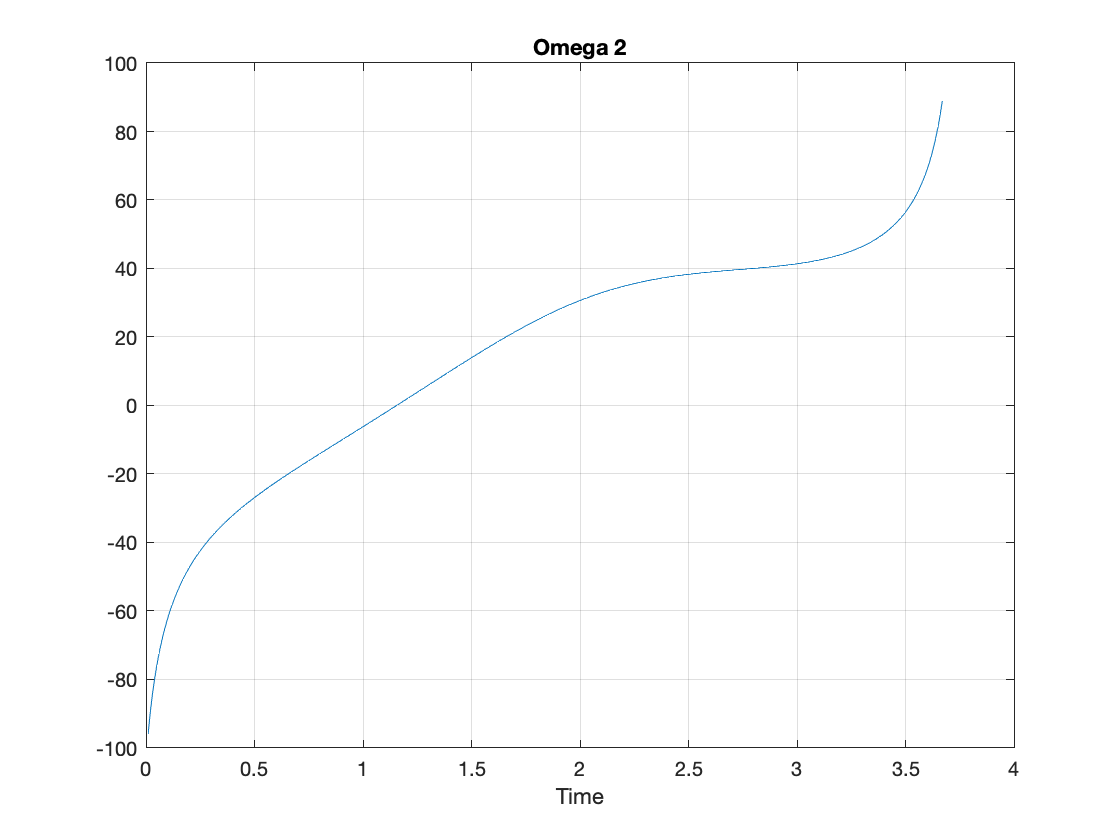


% close all;
% plot(B(:,1),B(:,2))
% hold on
% plot(C(:,1),C(:,2))
% 
% for i=1:length(th1)
% x=[A(i,1) B(i,1) C(i,1) D(i,1)];
% y=[A(i,2) B(i,2) C(i,2) D(i,2)];
% plot(x,y)  % to plot polygon
% 
% pause(.1)
% end



%Velocity
for i = 1:length(th1)
    A = [ r2*cosd(th2(i)) ,- r3*cosd(th3(i));...
          -r2*sind(th2(i)) ,+ r3*sind(th3(i)) ];
    B = [-r1*w1*cosd(th1(i));...
        r1*w1*sind(th1(i))];
    x = A\B;
    w2(i) = x(1,1);
    w3(i) = x(2,1);
end

%Acceleration
for i = 1:length(th1)
    A = [ r2*cosd(th2(i)) ,- r3*cosd(th3(i));...
          -r2*sind(th2(i)) ,+ r3*sind(th3(i)) ];
    
    B = [r1*w1^2*sind(th1(i)) + r2*w2(i)^2*sind(th2(i)) - r3*w3(i)^2*sind(th3(i));...
        r1*w1^2*cosd(th1(i)) + r2*w2(i)^2*cosd(th2(i)) - r3*w3(i)^2*cosd(th3(i))];
    x = A\B;
    a2(i) = x(1,1);
    a3(i) = x(2,1);
end

t1 = t;
t1(1) = [];
w2(1) = [];
w3(1) = [];
a2(1) = [];
a3(1) = [];

plot(t1,w2)
title("Omega 2")
xlabel("Time")
grid on

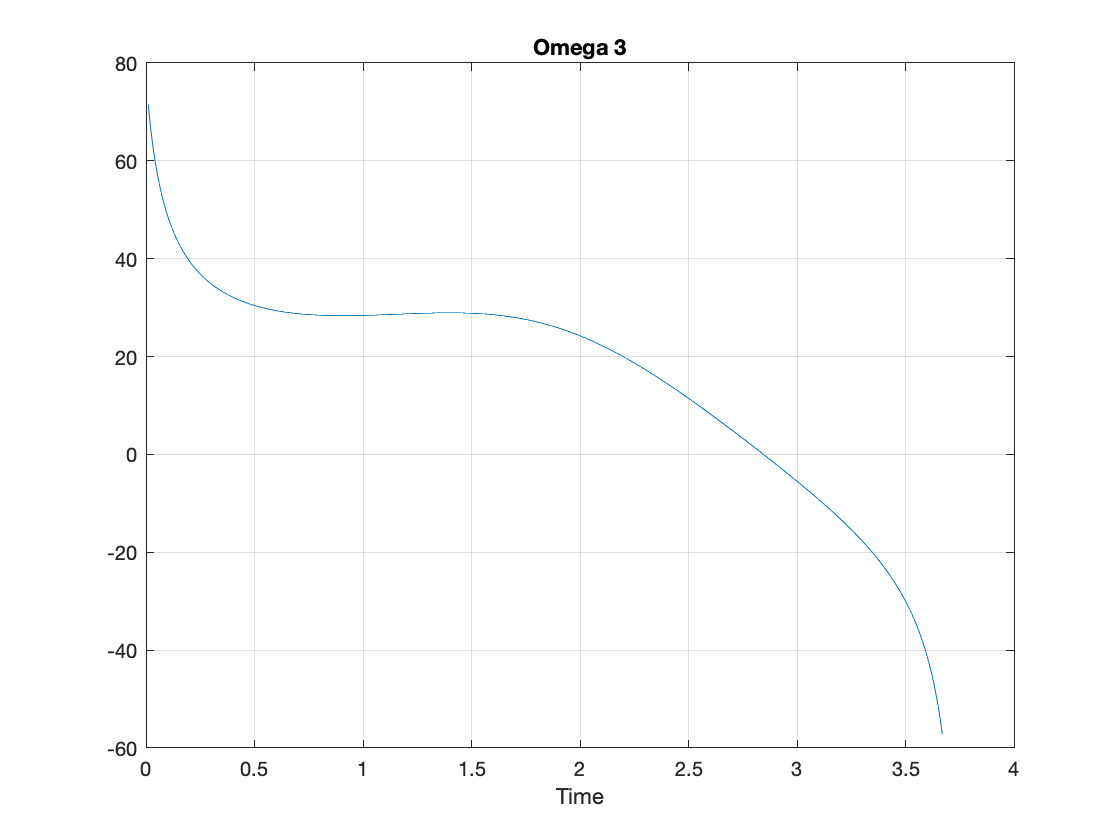



plot(t1,w3)
title("Omega 3")
xlabel("Time")
grid on

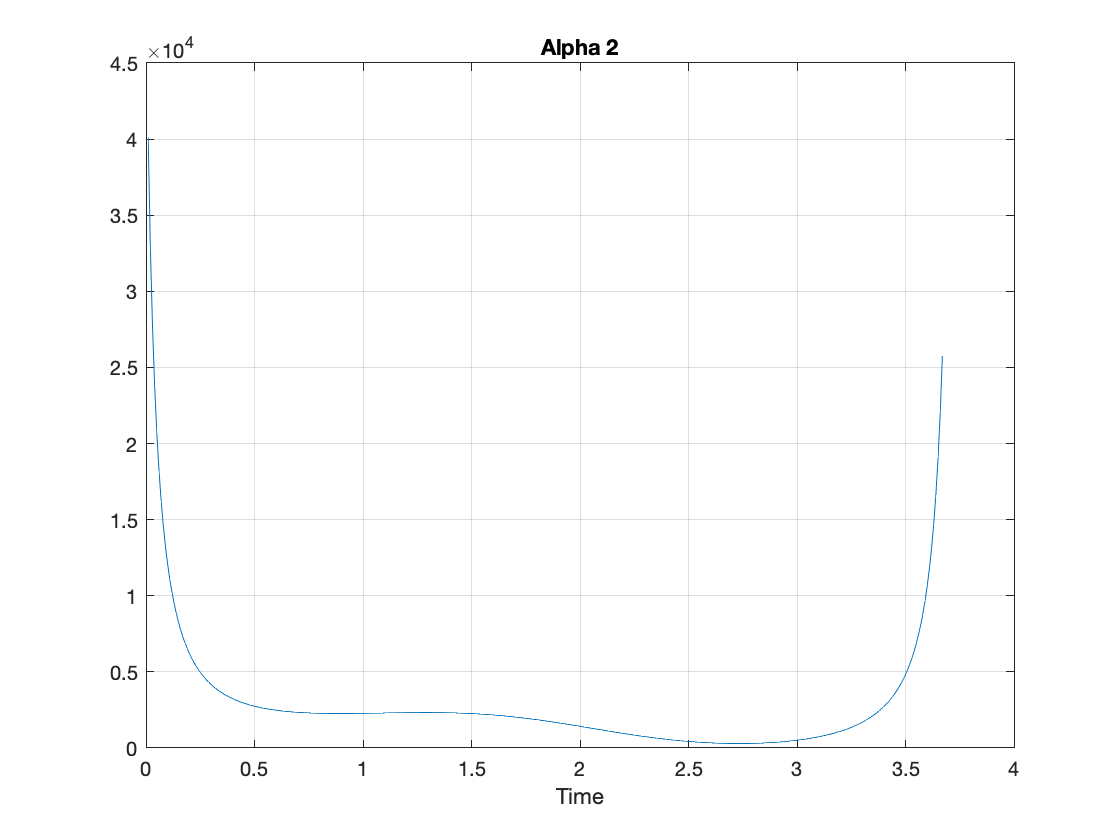



plot(t1,a2)
title("Alpha 2")
xlabel("Time")
grid on

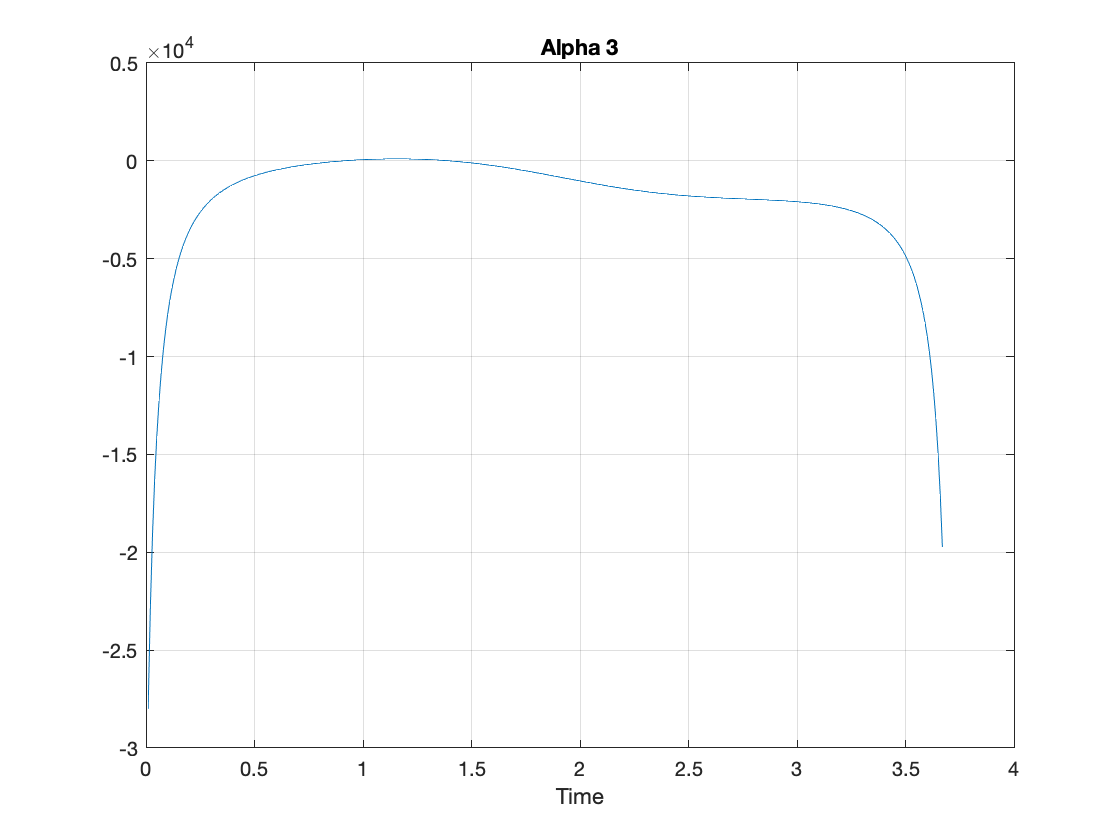


plot(t1,a3)
title("Alpha 3")
xlabel("Time")
grid on